# Q2. Steady State Temperature distribution in a 1D significant slab, with given Heat Generation rate.

### By, Anish Dhar. 211020067

- Initial Values

L = input("Enter Thickness of slab (in meters)")

L = 0.0200

dx = 0;
% Sc and St are the coefficients from Q = Sc + St * T
N_points = input("Enter Number of points at which solution is desired")

N_points = 20

K = input("Enter Thermal Conductivity (in W/m-K)")

K = 0.5000

Q_gen = 1000000; % W/m^3
area= 1 %m^2

area = 1

St = -1;
Sc = 1000;
Ti = input("Enter Temperature at First face (in °C)")

Ti = 100

P = 1 %m

P = 1

H = input("Enter Convective Heat Transfer coefficient");
To = input("Enter Temperature at Second face (in °C)")

To = 200

ANALYTICAL SOLUTION:

array_temps_analytical = zeros(N_points+2, 2);
dx = zeros(N_points + 2, 1);
for i = 2:1:N_points+1
dx(i) = L/N_points;
end
dx(1) = L/(N_points * 2);
dx(N_points+2) = L/(N_points * 2);

x(1) = 0;
for i = 2:1:N_points+2 % Getting all the points from the delta
x(i) = x(i-1) + dx(i-1);
end

% array_temps_analytical(1,1) = To;

for i = 1:1:N_points+2
array_temps_analytical(i,1) = Ti + ((To - Ti)/L)*x(i) + (Q_gen*L/(2*K))*x(i) - Q_gen*x(i)*x(i)/(2*K);
array_temps_analytical(i,2) = x(i);
% disp(array_temps(i))
end

NUMERICAL SOLUTION:

% Initializing important parameters for the given problem
x = zeros(N_points+2, 1); % For the unit lengths
a = zeros(N_points+2, 1); % For the right side of the matrix diagonal elements
b = zeros(N_points+2, 1); % For the left side of the matrix diagonal elements
d = zeros(N_points+2, 1); % For the diagonal Elements of the matrix
c = zeros(N_points+2, 1); % For the equation's answers

array_temps = zeros(N_points+2, 2); % For the equation's answers
dx = zeros(N_points + 2, 1); %Inter cell delta

for i = 2:1:N_points+1  %setting values for DX
    dx(i) = L/N_points;
end

dx(1) = L/(N_points * 2);
dx(N_points+2) = L/(N_points * 2);
% disp(dx)
x(1) = 0;

for i = 2:1:N_points+2   % Points for X-axis based on DX
    x(i) = x(i-1) + dx(i-1);
end

% Initial Boundary Conditions
a(1) = 0;
b(1) = 0;
c(1) = Ti;
d(1) = 1;
m2 = H*P/(K*area);
% Thermal Conductivity for the remaining points except for the last one
for i = 2:1:N_points+1
    d(i) = -(1/(dx(i-1)) + 1/dx(i+1) + m2*(dx(i+1) + dx(i-1))); % ST
    a(i) = (1/dx(i+1)); 
    b(i) = (1/dx(i-1));
    c(i) = (-m2*To- Q_gen)*(dx(i+1) + dx(i-1)); % SC
end

% Final Boundary Conditions
a(N_points + 2) = 0;
b(N_points + 2) = 0;
d(N_points + 2) = 1;
c(N_points + 2) = To;
for i = 2:1:N_points+2
d(i) = d(i) - b(i)*a(i-1)/d(i-1);
c(i) = c(i) - b(i)*c(i-1)/d(i-1);
end
for i = 1:1:N_points+2
disp(d(i));
end

     1

       -3000

  -1.6667e+03

       -1400

  -1.2857e+03

  -1.2222e+03

  -1.1818e+03

  -1.1538e+03

  -1.1333e+03

  -1.1176e+03

  -1.1053e+03

  -1.0952e+03

  -1.0870e+03

  -1.0800e+03

  -1.0741e+03

  -1.0690e+03

  -1.0645e+03

  -1.0606e+03

  -1.0571e+03

  -1.0541e+03

  -2.0513e+03

     1




% Final equations for back propogation
array_temps(N_points+2,1) = c(N_points+2)/d(N_points+2);
array_temps(N_points+2,2) = x(N_points+2);
% disp(array_temps(N_points+2))

for i = N_points+1:-1:1
array_temps(i,1) = (c(i) - a(i)*array_temps(i+1,1))/d(i);
array_temps(i,2) = x(i);
% disp(array_temps(i))
end



Plotting the Curves:

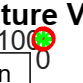

figure;

%for analytical graph
plot(array_temps_analytical(:,2),array_temps_analytical(:,1), 'g*-');
xlabel('Length');
ylabel('Temperature');
title('Temperature Variations');
grid on
hold on

%for numerical solution graph
plot(array_temps(:,2),array_temps(:,1), 'ro--');
xlabel('Length');
ylabel('Temperature');
title('Temperature Variations');

legend('Analytical Solution', 'Numerical Solution')
grid on
hold off

xlim([0 0.03])
ylim([100 270])